clear all;
clc;
% Load patients data
patients_table = readtable('radiomics_patients.csv');

% Load controls data
controls_table = readtable('radiomics_controls.csv');

% Display VariableNames of each table
disp('Patients VariableNames:');

Patients VariableNames:


disp(patients_table.Properties.VariableNames);

    {'Subject_ID'}    {'age'}    {'sex'}    {'Scanner'}    {'Inj_activity'}    {'Cohort'}    {'stat_qcod'}    {'ngt_complexity_3d_fbs_w0_0125'}    {'morph_pca_elongation'}    {'morph_diam'}    {'szm_zs_entr_3d_fbs_w0_0125'}    {'cm_joint_max_d1_3d_avg_fbs_w0_0125'}    {'dzm_zdnu_3d_fbs_w0_0125'}    {'ih_median_fbs_w0_0125'}    {'rlm_rlnu_3d_avg_fbs_w0_0125'}    {'stat_medad'}    {'cm_contrast_d1_3d_avg_fbs_w0_0125'}    {'morph_pca_flatness'}    {'morph_pca_maj_axis'}    {'ngl_ldlge_d1_a0_0_3d_fbs_w0_0125'}    {'cm_energy_d1_3d_avg_fbs_w0_0125'}



disp('Controls VariableNames:');

Controls VariableNames:


disp(controls_table.Properties.VariableNames);

    {'Subject_ID'}    {'Scanner'}    {'Inj_activity'}    {'age'}    {'sex'}    {'stat_qcod'}    {'ngt_complexity_3d_fbs_w0_0125'}    {'morph_pca_elongation'}    {'morph_diam'}    {'szm_zs_entr_3d_fbs_w0_0125'}    {'cm_joint_max_d1_3d_avg_fbs_w0_0125'}    {'dzm_zdnu_3d_fbs_w0_0125'}    {'ih_median_fbs_w0_0125'}    {'rlm_rlnu_3d_avg_fbs_w0_0125'}    {'stat_medad'}    {'cm_contrast_d1_3d_avg_fbs_w0_0125'}    {'morph_pca_flatness'}    {'morph_pca_maj_axis'}    {'ngl_ldlge_d1_a0_0_3d_fbs_w0_0125'}    {'cm_energy_d1_3d_avg_fbs_w0_0125'}



disp('Patients VariableNames:');

Patients VariableNames:


disp(patients_table.Properties.VariableNames);

    {'Subject_ID'}    {'age'}    {'sex'}    {'Scanner'}    {'Inj_activity'}    {'Cohort'}    {'stat_qcod'}    {'ngt_complexity_3d_fbs_w0_0125'}    {'morph_pca_elongation'}    {'morph_diam'}    {'szm_zs_entr_3d_fbs_w0_0125'}    {'cm_joint_max_d1_3d_avg_fbs_w0_0125'}    {'dzm_zdnu_3d_fbs_w0_0125'}    {'ih_median_fbs_w0_0125'}    {'rlm_rlnu_3d_avg_fbs_w0_0125'}    {'stat_medad'}    {'cm_contrast_d1_3d_avg_fbs_w0_0125'}    {'morph_pca_flatness'}    {'morph_pca_maj_axis'}    {'ngl_ldlge_d1_a0_0_3d_fbs_w0_0125'}    {'cm_energy_d1_3d_avg_fbs_w0_0125'}



disp('Controls VariableNames:');

Controls VariableNames:


disp(controls_table.Properties.VariableNames);

    {'Subject_ID'}    {'Scanner'}    {'Inj_activity'}    {'age'}    {'sex'}    {'stat_qcod'}    {'ngt_complexity_3d_fbs_w0_0125'}    {'morph_pca_elongation'}    {'morph_diam'}    {'szm_zs_entr_3d_fbs_w0_0125'}    {'cm_joint_max_d1_3d_avg_fbs_w0_0125'}    {'dzm_zdnu_3d_fbs_w0_0125'}    {'ih_median_fbs_w0_0125'}    {'rlm_rlnu_3d_avg_fbs_w0_0125'}    {'stat_medad'}    {'cm_contrast_d1_3d_avg_fbs_w0_0125'}    {'morph_pca_flatness'}    {'morph_pca_maj_axis'}    {'ngl_ldlge_d1_a0_0_3d_fbs_w0_0125'}    {'cm_energy_d1_3d_avg_fbs_w0_0125'}



% Compare mean and SD of demographics (age and gender)
patients_age_mean = mean(patients_table.age);
patients_age_std = std(patients_table.age);
controls_age_mean = mean(controls_table.age);
controls_age_std = std(controls_table.age);

fprintf('Patients: Mean Age = %.2f, SD = %.2f\n', patients_age_mean, patients_age_std);

Patients: Mean Age = 29.40, SD = 7.34


fprintf('Controls: Mean Age = %.2f, SD = %.2f\n', controls_age_mean, controls_age_std);

Controls: Mean Age = 28.75, SD = 7.92



% Compare gender distribution qualitatively (not shown here)

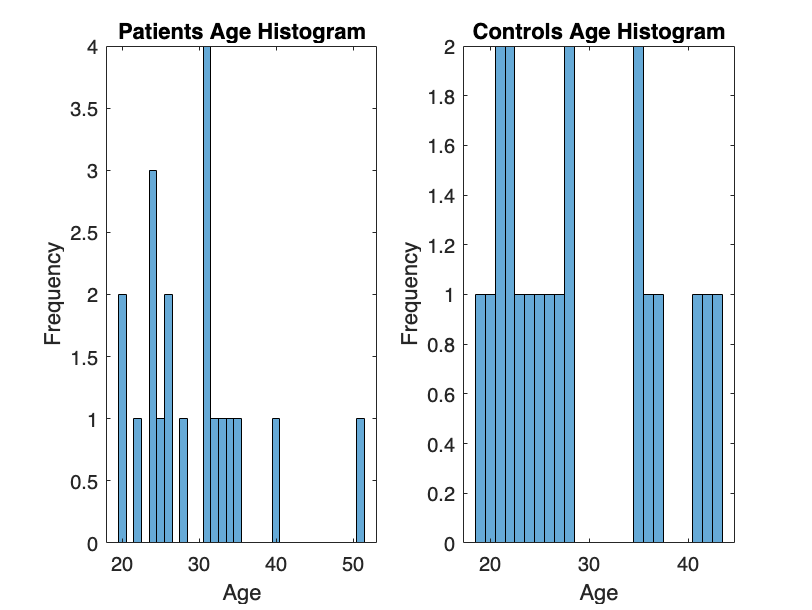

% Histogram of age for patients and controls
figure;
subplot(1,2,1);
histogram(patients_table.age);
title('Patients Age Histogram');
xlabel('Age');
ylabel('Frequency');

subplot(1,2,2);
histogram(controls_table.age);
title('Controls Age Histogram');
xlabel('Age');
ylabel('Frequency');

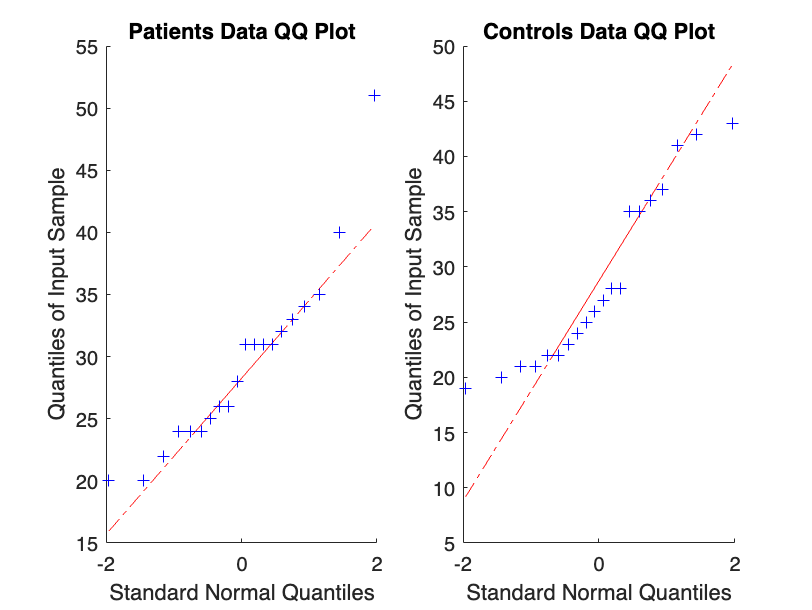

% QQ plot of target variables for patients and controls
figure;
subplot(1,2,1);
qqplot(patients_table.age); % Replace 'variablename' with actual variable name
title('Patients Data QQ Plot');

subplot(1,2,2);
qqplot(controls_table.age); % Replace 'variablename' with actual variable name
title('Controls Data QQ Plot');

% Extract age and sex columns from controls_table
controls_demographics = controls_table(:, {'age', 'sex'});

% Convert the 'sex' column to categorical for compatibility
controls_demographics.sex = categorical(controls_demographics.sex);

% Extract the target variable from controls_table
controls_target_variable = controls_table.age; % Replace 'variablename' with the actual variable name

% Compute Spearman correlation between the target variable and demographics data
spearman_corr = corr(controls_target_variable, controls_demographics.age, 'Type', 'Spearman');

% Display the results
disp('Spearman Correlation:');

Spearman Correlation:


disp(spearman_corr);

    1.0000




% Cross-tabulation between target variable and gender in controls
crosstab_gender = crosstab(controls_target_variable, controls_demographics.sex);

% Display the results
disp('Cross-tabulation (gender):');

Cross-tabulation (gender):


disp(crosstab_gender);

     0     1
     1     0
     1     1
     1     1
     0     1
     1     0
     1     0
     1     0
     0     1
     0     2
     1     1
     1     0
     0     1
     0     1
     1     0
     0     1

